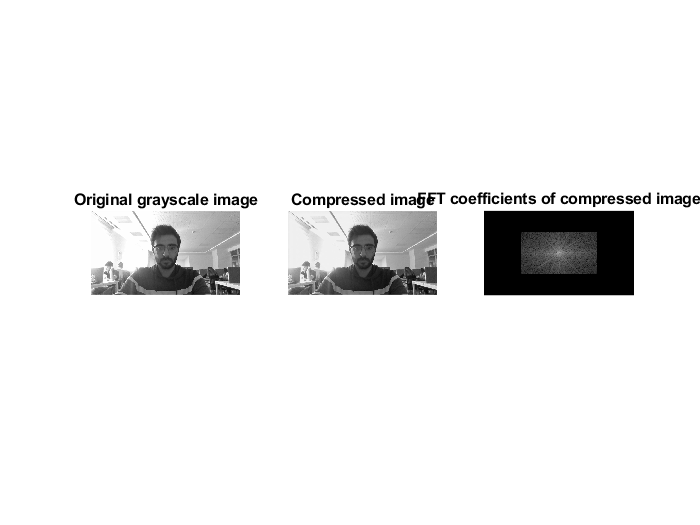

tic;
ahmet=imread("C:\Users\ahmet\Desktop\4.sınıf\image\mp4\ahmet.jpg");
ahmet_gray=rgb2gray(ahmet);
ahmet_gray=im2double(ahmet_gray); 

[r c]=size(ahmet_gray);

fftahmet = fft2(ahmet_gray,r,c);
fftshifted = fftshift(fftahmet);

[rows, cols] = size(fftshifted);
crow = round(rows / 2);
ccol = round(cols / 2);
half_row = round(rows / 4);
half_col = round(cols / 4);

fft_compressed = zeros(size(fftshifted));
fft_compressed(crow-half_row:crow+half_row, ccol-half_col:ccol+half_col) = fftshifted(crow-half_row:crow+half_row, ccol-half_col:ccol+half_col);

compressed_image = real(ifft2(ifftshift(fft_compressed)));

figure;
subplot(131);
imshow(ahmet_gray);
title('Original grayscale image');
subplot(132);
imshow(compressed_image, []);
title('Compressed image');
subplot(133);
imshow(log(abs(fft_compressed) + 1), []);
title('FFT coefficients of compressed image');


compressed_fft_size = numel(find(fft_compressed));
original_fft_size = numel(fftahmet);
compression_ratio = compressed_fft_size / original_fft_size * 100;
fprintf("original fft size %f \n",original_fft_size);

original fft size 921600.000000 


fprintf("compressed fft size %f \n",compressed_fft_size);

compressed fft size 231401.000000 


fprintf('The FFT size of the compressed image is %%%f of the original FFT size.\n', compression_ratio);

Sıkıştırılmış resmin FFT boyutu, orijinal FFT boyutunun % 25.108615 kadarıdır.



toc;

Elapsed time is 9.025254 seconds.


Unrecognized function or variable 'time'.